# Solution to *Escape Velocity II* exercise

## Set parameters

M = 1.02e26;
R = 2.47e7;

## Call function to do everything else

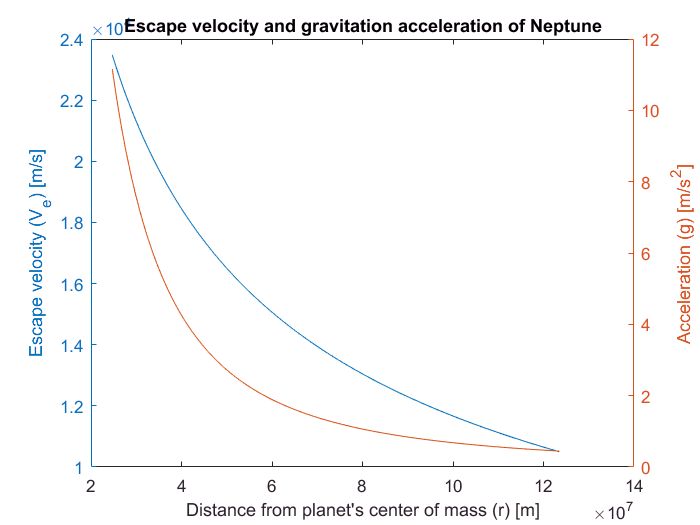

[Ve,g] = veandg('Neptune',M,R); 

## Local function

Function to calculate and plot $V_e$ and $g$ according to the formulae

$V_e = \sqrt{\frac{2GM}{r}} $  and  $g = \frac{GM}{r^2}$

function [Ve,g] = veandg(pname,M,R)
    G = 6.673e-11;
    r = linspace(R,5*R);
    Ve = sqrt(2*G*M./r);
    g = G*M./(r.^2);
    
    % Plot escape velocity on left y-axis
    yyaxis left
    plot(r,Ve)
    ylabel('Escape velocity (V_e) [m/s]')
    % Plot gravitational acceleration on right y-axis
    yyaxis right
    plot(r,g)
    ylabel('Acceleration (g) [m/s^2]')
    % Add title and x-axis label
    xlabel('Distance from planet''s center of mass (r) [m]')
    title(['Escape velocity and gravitation acceleration of ',pname])
end